rng(0);   %random seed
clear;

Read all instructions before you start. Generate N points (with N- taking the values 10, 102 , 103 , 104 , 105 ) from a multivariate 2D Gaussian probability density function with mean µ = [1, 2]'

N = [10,10^2,10^3,10^4,10^5];   %values of N
mean = [1;2];   %mean vector

 and a covariance matrix C with the first row as [1.6250, -1.9486] and the second row as [-1.9486, 3.8750]. For this generation, you are only allowed to use the randn() and eig() functions in Matlab. 

C = [1.6250, -1.9486;-1.9486, 3.8750];   %covariance matrix

For each data sample of size N, compute the maximum-likelihood (ML) estimates of the mean and the covariance matrix. For this estimation, you are only allowed to use the sum() function in Matlab. 

(a) (5 points) Describe and justify your method for generating sample points from the 2D Gaussian. 

Ref the report for the description.

[Q,D] = eig(C)  %calculate eigenvalues and eigenvectors

Q =    -0.8660   -0.5000
   -0.5000    0.8660


D =     0.5000         0
         0    5.0000


%generating 1 draw at a time, replace 1 with relevant num
Y = Q*(sqrt(D)*randn(2,1))+ mean   %refer to report for proof

Y =    -1.3796
    5.3612


(b) (5 points) For each value of N, repeat the experiment 100 times, and plot a boxplot of the error between the true mean µ and the ML estimate µbN (which depends on N), where the error measure is k µ - µbN k2 / k µ k2. Use a logarithmic scale on the horizontal axis, i.e., log10 N. 

(c) (5 points) For each value of N, repeat the experiment 100 times, and plot a boxplot of the error between the true covariance C and the ML estimate CbN (which depends on N), where the error measure is k C - CbN kFro / k C kFro. Use a logarithmic scale on the horizontal axis, i.e., log10 N. 

We do both together

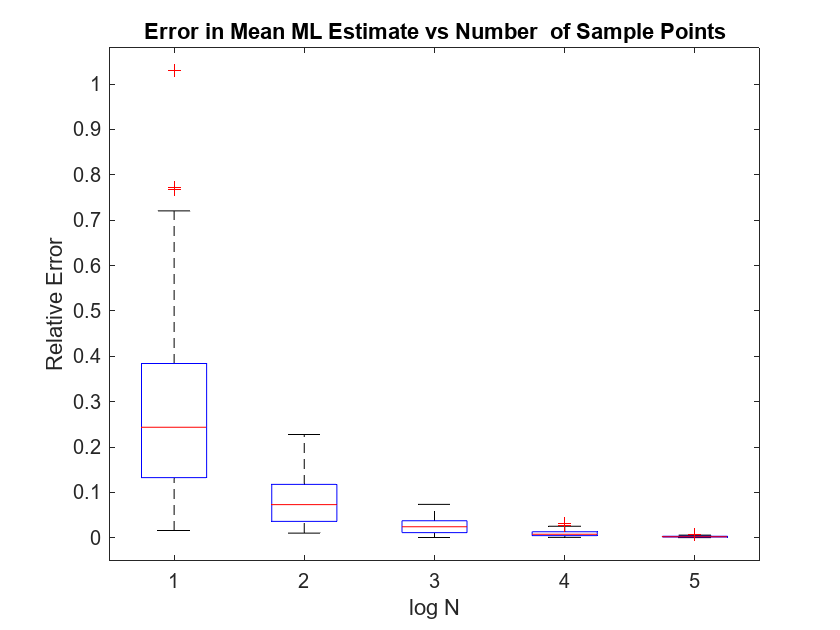

mean_errors = zeros(100,length(N)); %vector to store the errors in mean ML estimator
cov_errors = zeros(100,length(N));  %vector to store the erros in covariance ML estimator
util = Q*sqrt(D);  %utility matrix, will be used later to transform to gaussian distribution

for n = N
    errors = zeros(100, 1);
    errors2 = zeros(100, 1);
    for i = 1:100       
        rand_draws = randn(2,n);   %generate standard gaussian variables first
        gauss = util*rand_draws + mean;     %transform to the desired gaussian
        mean_calc = sum(gauss,2)/n;  %ML mean estimate
        errors(i) = norm(mean_calc - mean)/norm(mean);    %error in mean
        cov_matrix = ((gauss-mean_calc)*(gauss-mean_calc)')/n;   %ML covariance estimate
        errors2(i) = norm(cov_matrix - C, "fro")/norm(C, "fro");   %error in covariance
    end
    mean_errors(:,log10(n)) = errors;
    cov_errors(:,log10(n)) = errors2;
end

boxplot(mean_errors);
xlabel('log N');
ylabel('Relative Error');
title('Error in Mean ML Estimate vs Number  of Sample Points');

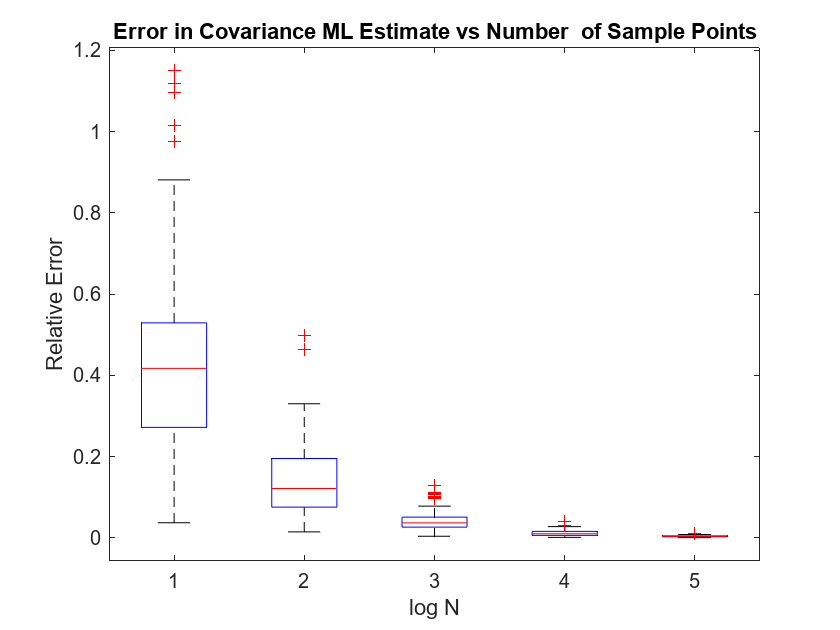


boxplot(cov_errors)
xlabel('log N');
ylabel('Relative Error');
title('Error in Covariance ML Estimate vs Number  of Sample Points');

(d) (5 points) For each value of N, for a single data sample, within a single figure, plot the 2D scatter plot of the generated data and show the principal modes of variation of the data by plotting a line starting at the empirical mean and going a distance equal to the empirical eigen-value’s square root along a direction given by the empirical eigen-vector.

e_val =     5.3005
    0.4803


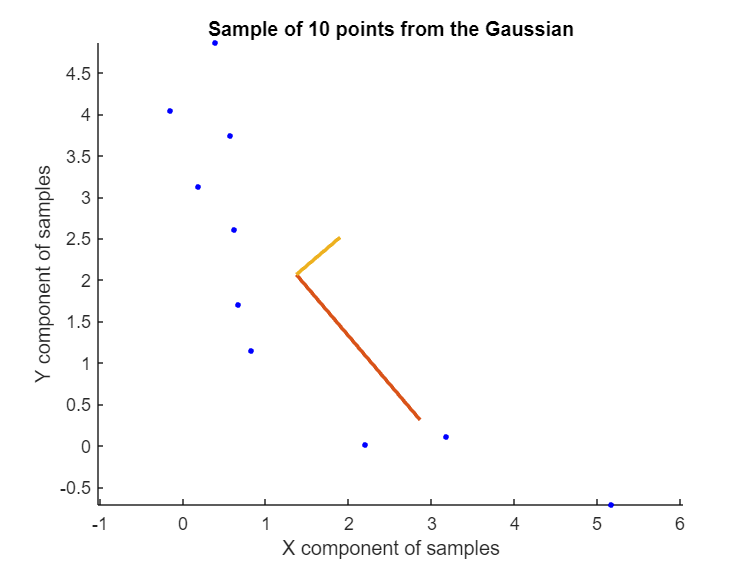

e_val =     5.2943
    0.3708


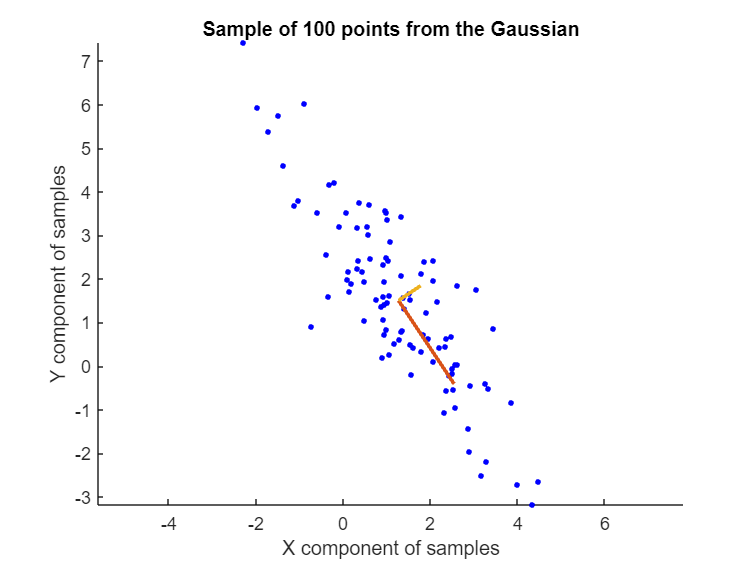

e_val =     4.8549
    0.4883


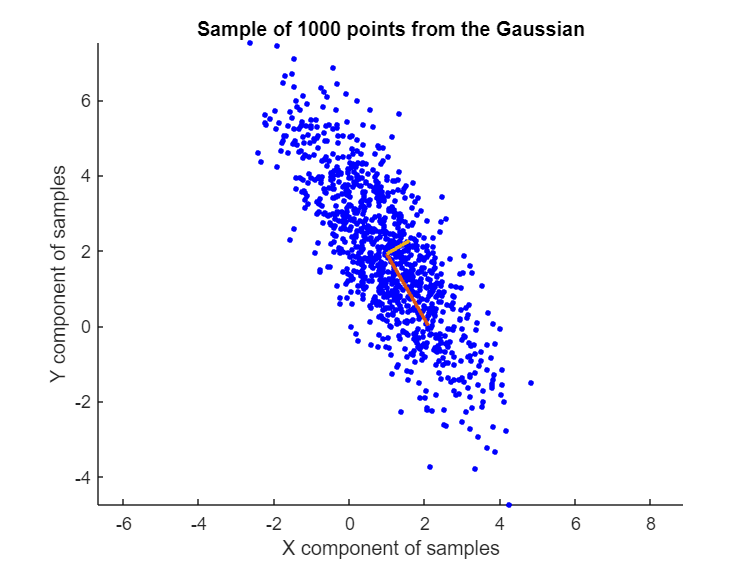

e_val =     4.9604
    0.4990


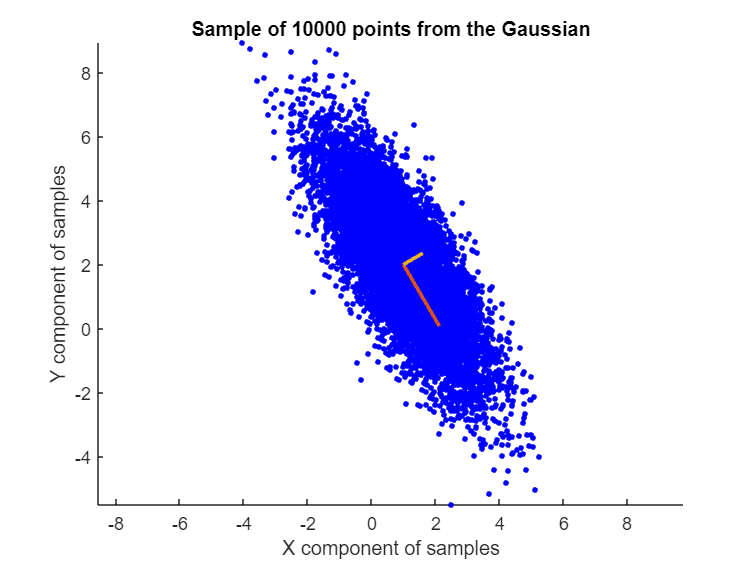

e_val =     5.0115
    0.4992


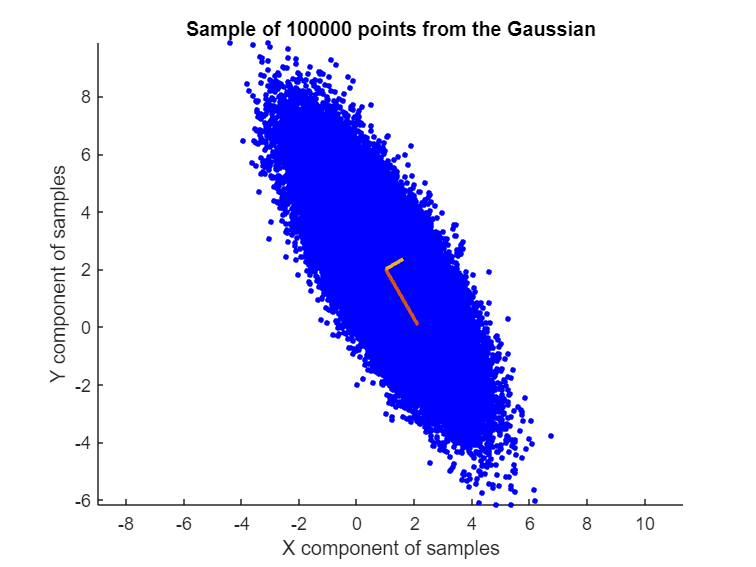

for n = N
    %4 lines same as above
    rand_draws = randn(2,n);
    gauss = util*rand_draws + mean;  
    mean_calc = sum(gauss,2)/n;
    cov_matrix = ((gauss-mean_calc)*(gauss-mean_calc)')/n;
     
    [e_vec, e_val] = eigs(cov_matrix, 2);  %principal eigenvectors/values
    e_val = diag(e_val)
    %used to plot principal eigenvectors' directions
    fin1 = mean_calc - sqrt(e_val(1))*e_vec(:, 1);  
    fin2 = mean_calc - sqrt(e_val(2))*e_vec(:, 2);

    figure,    
    scatter(gauss(1,:), gauss(2,:), 10, "blue", "filled"); 
    title("Sample of "+n+" points from the Gaussian");
    xlabel('X component of samples')
    ylabel('Y component of samples')
    axis equal
    hold on
    
    plot([mean_calc(1) fin1(1)], [mean_calc(2) fin1(2)], "LineWidth", 2);     
    hold on
    plot([mean_calc(1) fin2(1)], [mean_calc(2) fin2(2)], "LineWidth", 2);    
    hold off
    

end